# Ejercicios SS 

Universidad Nacional de Colombia

Técnicas de control

2023

Andrés Holguin restrepo

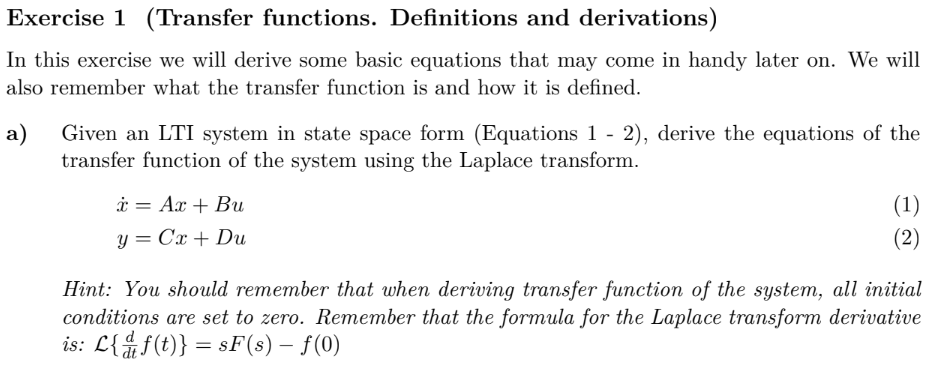

Escribiendo las ecuaciones en el dominio de Laplace, donde se tiene en cuenta condiciones iniciales f(0)=0:


$$\begin{array}{l}
\mathrm{sX}\left(s\right)-f\left(0\right)=\mathrm{AX}\left(s\right)+\mathrm{BU}\left(s\right)\\
\mathrm{sX}\left(s\right)=\mathrm{AX}\left(s\right)+\mathrm{BU}\left(s\right)\\
\\
Y\left(s\right)=\mathrm{CX}\left(s\right)+\mathrm{DU}\left(s\right)
\end{array}$$


Ahora se multiplica la segunda ecuación por $U\left(s{\left.\right)}^{-1} \right.$ para poder obtener la relación Y(s)/U(s) y de este modo la función de transferencia


$$\frac{Y\left(s\right)}{U\left(s\right)}=\mathrm{CX}\left(s\right){U\left(s\right)}^{-1} +D$$


Despejando X(s) de la primera ecuación:


$$X\left(s\right)={\left(\mathrm{sI}-A\right)}^{-1} \mathrm{BU}\left(s\right)$$


Remplazando $X\left(s\right)$ en el resultado anterior:


$$\frac{Y\left(s\right)}{U\left(s\right)}={C\left(\mathrm{sI}-A\right)}^{-1} B+D$$


De este modo se obtiene la función de transferencia.

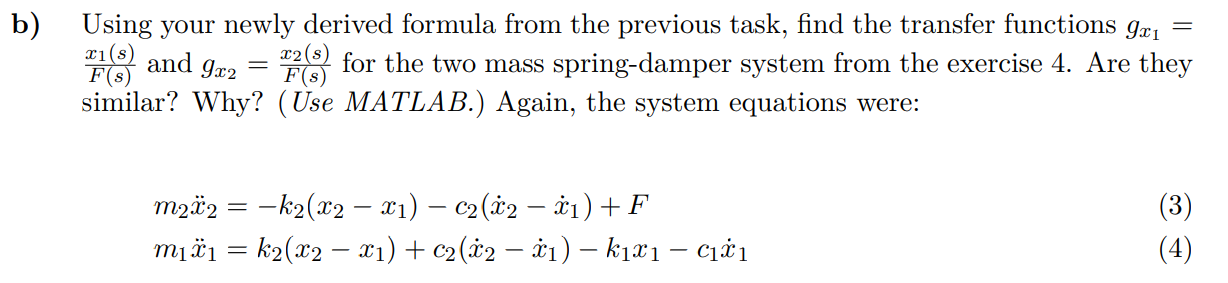

Se reescriben estas dos ecuaciones en un modelo de variables de estado, teniendo en cuenta que:


$$\left\lbrack \begin{array}{c}
x_1 \\
\dot{x_1 } \\
x_2 \\
\dot{x_2 } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\theta_1 \\
\theta_2 \\
\theta_3 \\
\theta_4 
\end{array}\right\rbrack$$
                
$$\begin{array}{l}
\theta_2 =\dot{\theta_1 } \\
\theta_4 =\dot{\theta_3 } 
\end{array}$$


De este modo, se tiene que:


$$\theta^˙ =\left\lbrack \begin{array}{cccc}
0 & 1 & 0 & 0\\
-\frac{k_1 +k_2 }{m_1 } & -\frac{c_1 +c_2 }{m_1 } & \frac{k_2 }{m_1 } & \frac{c_2 }{m_1 }\\
0 & 0 & 0 & 1\\
\frac{k_2 }{m_2 } & \frac{c_2 }{m_2 } & -\frac{k_2 }{m_2 } & -\frac{c_2 }{m_2 }
\end{array}\right\rbrack \theta +\left\lbrack \begin{array}{c}
0\\
0\\
0\\
\frac{1}{m_2 }
\end{array}\right\rbrack F$$


Para el caso: $g_{\mathrm{x1}} \left(s\right)$


$$Y\left(s\right)=\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0
\end{array}\right\rbrack \theta$$


Para el caso: $g_{\mathrm{x2}} \left(s\right)$


$$Y\left(s\right)=\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0
\end{array}\right\rbrack \theta$$


De este modo se determinan las funciones de transferencia:

syms k_1 k_2 c_1 c_2 s m_1 m_2 s F
A=[0 1 0 0; -(k_1+k_2)/m_1 -(c_1+c_2)/m_1 k_2/m_1 c_2/m_1;0 0 0 1; k_2/m_2 c_2/m_2 -k_2/m_2 -c_2/m_2];
B=[0 0 0 1/m_2].';C_x1=[1 0 0 0];C_x2=[0 0 1 0];D=0;
G_x1=simplify(collect(C_x1*(s*eye(4)-A)^-1*B+D,s))

$$G\_x1 = \frac{c_{2}\,s+k_{2}}{\left(m_{1}\,m_{2}\right)\,s^{4}+\left(c_{1}\,m_{2}+c_{2}\,m_{1}+c_{2}\,m_{2}\right)\,s^{3}+\left(c_{1}\,c_{2}+k_{1}\,m_{2}+k_{2}\,m_{1}+k_{2}\,m_{2}\right)\,s^{2}+\left(c_{1}\,k_{2}+c_{2}\,k_{1}\right)\,s+k_{1}\,k_{2}}$$

G_x2=simplify(collect(C_x2*(s*eye(4)-A)^-1*B+D,s))

$$G\_x2 = \frac{m_{1}\,s^{2}+\left(c_{1}+c_{2}\right)\,s+k_{1}+k_{2}}{\left(m_{1}\,m_{2}\right)\,s^{4}+\left(c_{1}\,m_{2}+c_{2}\,m_{1}+c_{2}\,m_{2}\right)\,s^{3}+\left(c_{1}\,c_{2}+k_{1}\,m_{2}+k_{2}\,m_{1}+k_{2}\,m_{2}\right)\,s^{2}+\left(c_{1}\,k_{2}+c_{2}\,k_{1}\right)\,s+k_{1}\,k_{2}}$$

Analizando los dos resultados, se determina que ambos tienen el mismo polinomio característico debido a que parten del mismo sistema, sin embargo el numerador cambia entre las dos funciones de transferencia teniendo en cuenta la salida de cada una de estas.

Realizando la transformada de laplace asumiendo condiciones iniciales nulas:


$$s^2 Y\left(s\right)+5\mathrm{sY}\left(s\right)+10Y\left(s\right)=\mathrm{sU}\left(s\right)+10U\left(s\right)$$


Resolviendo para Y(s)/U(s):


$$\frac{Y\left(s\right)}{U\left(s\right)}=\frac{s+10}{s^2 +5s+10}$$


## 3

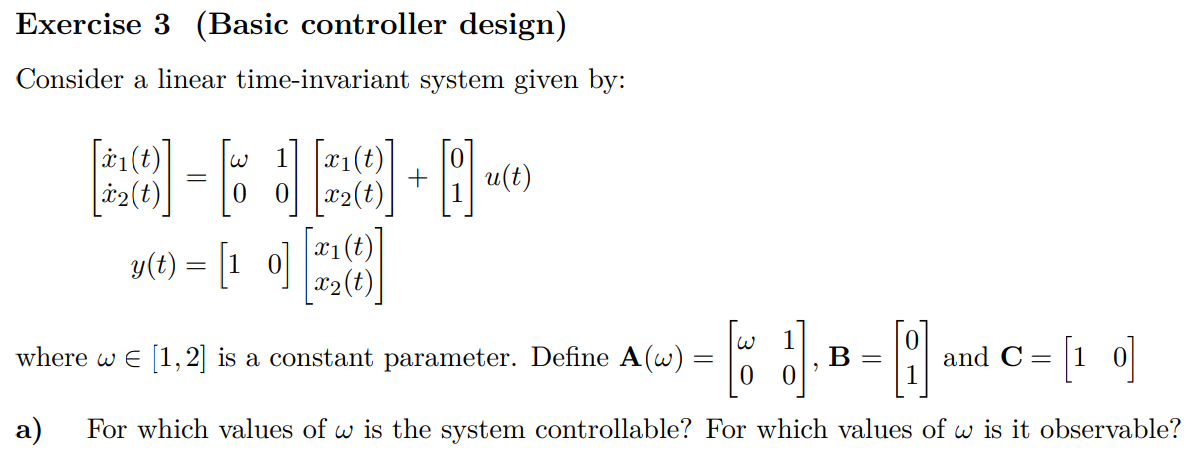

clear
syms omega;
A=[omega 1; 0 0];B=[0;1];C=[1 0];

Primero se calcula la matriz de controlabilidad:


$$C_M =\left\lbrack B\;\mathrm{AB}\right\rbrack$$


CM=[B A*B]

$$CM = \left(\begin{array}{cc} 0 & 1\\ 1 & 0 \end{array}\right)$$

det(CM)

$$ans = -1$$

rank(CM)

ans = 2

Como se evidencia, el determinante es -1 y el rango siempre es 2 independientemente de $\omega$, por lo que el sistema es controlable para cualquier valor $\omega$.

Ahora se calcula la matriz de observabilidad:

OM=[C;C*A]

$$OM = \left(\begin{array}{cc} 1 & 0\\ \omega & 1 \end{array}\right)$$

det(OM)

$$ans = 1$$

rank(OM)

ans = 2

Como se evidencia, el determinante es 1 y asi mismo el rango siempre es 2, independientemente de $\omega$,  por lo que el sistema es observable para cualquier valor $\omega$.

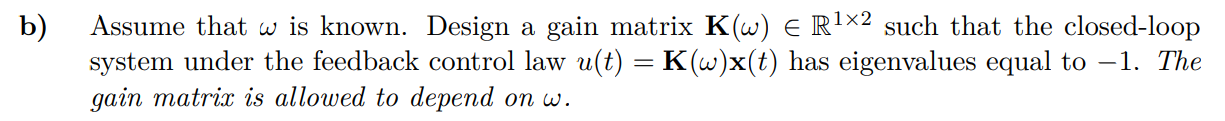

Los eigenvalores de lazo cerrado del sistema se pueden determinar mediante las raices de la ecuación característica: det(sI − (A − BK)) = 0

syms s k_1 k_2
K=[k_1,k_2]

$$K = \left(\begin{array}{cc} k_{1} & k_{2} \end{array}\right)$$

collect(det(s*eye(2) -(A - B*K))==0,s)

$$ans = s^{2}+\left(k_{2}-\omega \right)\,s+k_{1}-k_{2}\,\omega =0$$

de este modo, para obtener valores de eigenvalores -1, se soluciona para:


$$s^2 +{\left(k_2 -\omega \right)}\,s+k_1 -k_2 \,\omega ={\left(s+1\right)}^2 =s^2 +2s+1=0$$


De este modo, agrupando valores, se tiene que:


$$\begin{array}{l}
2=k_2 -\omega \\
1=k_1 -k_2 \omega 
\end{array}$$


Solucionando:


$$\begin{array}{l}
k_2 =2+\omega \\
k_1 =1+2\omega +\omega^2 
\end{array}$$



$$K=\left\lbrack \begin{array}{c}
1+2\omega +\omega^2 \\
2+\omega 
\end{array}\right\rbrack$$


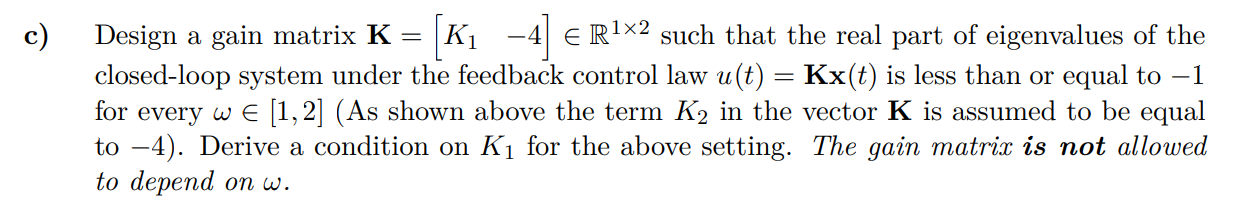

(no está terminado el desarrollo)

Para $\omega =2$

omega=2;
A=[omega 1; 0 0];B=[0;1];C=[1 0];
syms k_1
K=[k_1,-4]

$$K = \left(\begin{array}{cc} k_{1} & -4 \end{array}\right)$$

Eig2=solve(collect(det(s*eye(2) -(A - B*K)),s)==0)

$$Eig2 = \left(\begin{array}{c} 3-\sqrt{1-k_{1}}\\ \sqrt{1-k_{1}}+3 \end{array}\right)$$

solve(Eig2(1)==-1,k_1)

$$ans = -15$$

solve(Eig2(2)==-1)

 
ans =
 
Empty sym: 0-by-1
 


Para $\omega =1$

omega=1;
A=[omega 1; 0 0];B=[0;1];C=[1 0];
Eig1=solve(collect(det(s*eye(2) -(A - B*K)),s)==0)

$$Eig1 = \left(\begin{array}{c} \frac{5}{2}-\frac{\sqrt{9-4\,k_{1}}}{2}\\ \frac{\sqrt{9-4\,k_{1}}}{2}+\frac{5}{2} \end{array}\right)$$

solve(Eig1(1)==-1)

$$ans = -10$$

solve(Eig1(2)<=-1)

 
ans =
 
Empty sym: 0-by-1
 


Se establece entonces un valor $K_1 =-15$. Este permite que uno de los eigenvalores siempre tenga valor real menor o igual a 1 para el rango $\omega \in \left\lbrack 1,2\right\rbrack$

K=[-15,-4];

Para $\omega =2$

omega=2;A=[omega 1; 0 0];
Eig2=double(solve(collect(det(s*eye(2) -(A - B*K)),s)==0))

Eig2 =     -1
     7


Para $\omega =1$

omega=1;A=[omega 1; 0 0];
Eig1=double(solve(collect(det(s*eye(2) -(A - B*K)),s)==0))

Eig1 =    -1.6533
    6.6533
